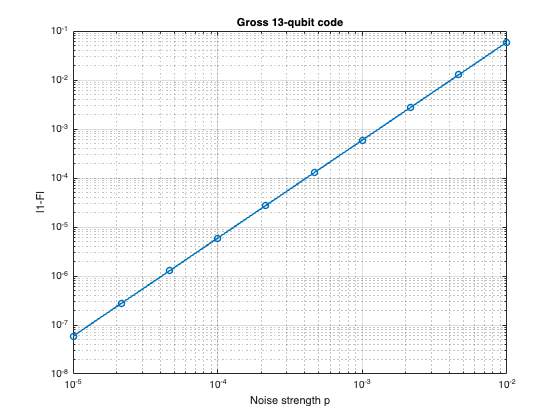

% Get codewords
[l0, l1] = codewords.gross_spin13();

% Parameters
noisetype = 'globalsymmetric';
method    = 'direct';
dim       = length(l0);

% p list: log-spaced between 1e-4 and 1e-2
p_list = logspace(-5, -2, 10);

% Allocate fidelity array
fid = zeros(size(p_list));

% Maximally mixed logical state
rhoL = eye(2) / 2;

% Loop over noise strengths
for k = 1:length(p_list)
    p = p_list(k);

    % Build noise model
    kraus = noisemodel(noisetype, p, dim);

    % Run optimisation
    [fid(k), ~, ~] = optimisation(l0, l1, kraus, rhoL, 1, method);
end

% Infidelity
infidelity = abs(1 - fid);

% Plot: log-log with grid
figure;
loglog(p_list, infidelity, 'o-', 'LineWidth', 1.5);
grid on;
grid minor;

xlabel('Noise strength p');
ylabel('|1-F|')
title('Gross 13-qubit code');